# **Matlab案例代码解析**

## 1. 基础函数使用案例

### 1.1  基础知识技巧

#### 1.1.17 gridfit散点插值成曲面

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

**下载链接：**[https://ww2.mathworks.cn/matlabcentral/fileexchange/8998-surface-fitting-using-gridfit](https://ww2.mathworks.cn/matlabcentral/fileexchange/8998-surface-fitting-using-gridfit)

Matlab2020B 自带有了 gridfit 函数

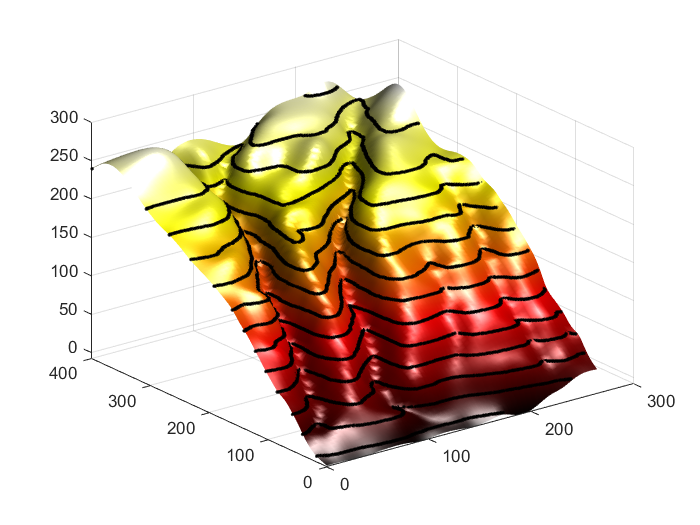

clear;clc;close all;
[all_themes, all_colors] = GetColors();
% 案例一
load data\bluff_data;
x = bluff_data(:, 1);
y = bluff_data(:, 2);
z = bluff_data(:, 3);
% 细化
gx = 0:4:264;
gy = 0:4:400;
g = gridfit(x, y, z, gx, gy);
figure
colormap(hot(256));
surf(gx, gy, g);
camlight right;
lighting phong;
shading interp
hold on
plot3(x, y, z, '.k');
hold off

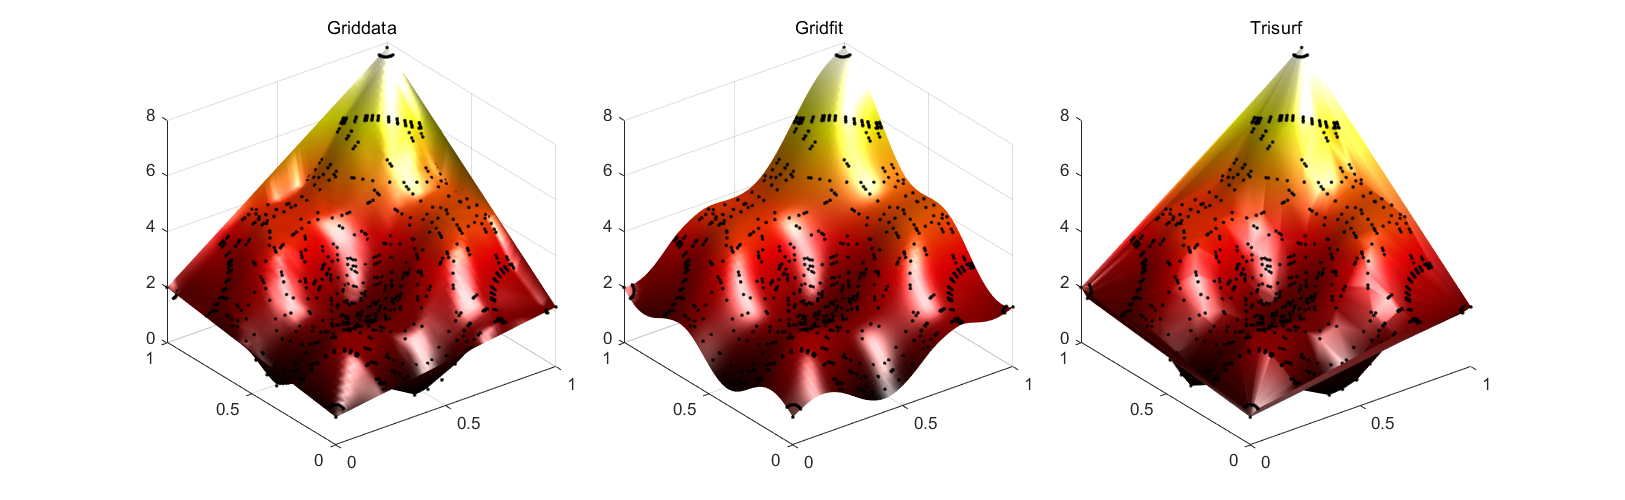

% 案例二
n1 = 15;
n2 = 15;
theta = rand(n1, 1)*pi/2;
r = rand(1, n2);
x = cos(theta)*r;
y = sin(theta)*r;
x = x(:);
y = y(:);
x = [[0 0 1 1]'; x; x; 1-x; 1-x];
y = [[0 1 0 1]'; y; 1-y; y; 1-y];
z = sin(4*x + 5*y) .* cos(7*(x - y)) + exp(x + y);
xi = linspace(0, 1, 51);
[xg, yg] = meshgrid(xi, xi);
zgd = griddata(x, y, z, xg, yg);
figure('Position', [10, 10, 1300, 400])
tiledlayout(1, 3, 'TileSpacing', 'compact');
nexttile
surf(xi, xi, zgd)
hold on
plot3(x, y, z, '.k');
hold off
colormap(hot(256))
camlight right
lighting phong
shading interp
title('Griddata')
zgrid = gridfit(x, y, z, xi, xi);
nexttile
surf(xi, xi, zgrid)
hold on
plot3(x, y, z, '.k');
hold off
colormap(hot(256))
camlight right
lighting phong
shading interp
title('Gridfit')
nexttile
% 网格化
tri = delaunay(x, y);
plot3(x, y, z, '.k')
hold on
trisurf(tri, x, y, z);
colormap(hot(256));
hold off
camlight right;
lighting phong;
shading interp
title('Trisurf')

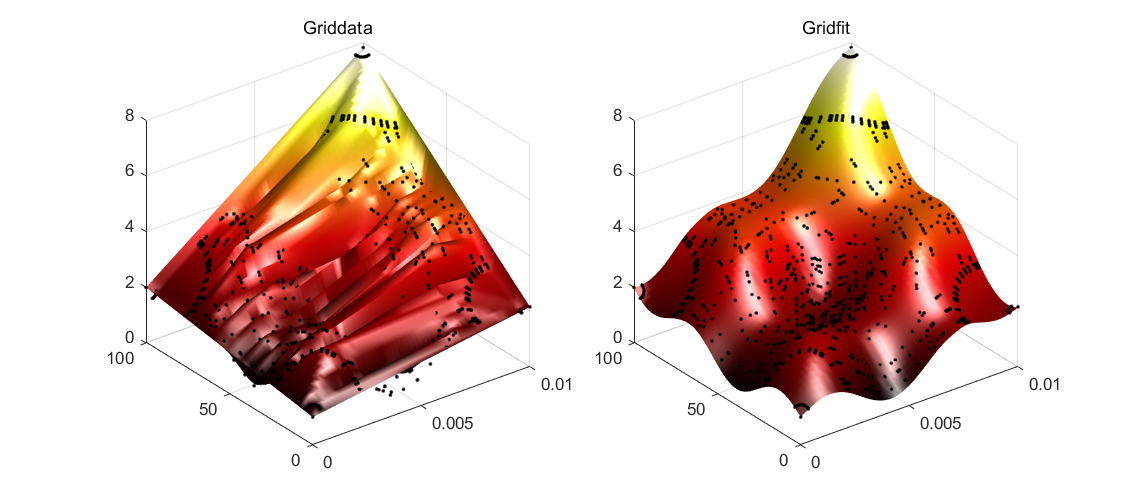

xs = x/100;
xis = xi/100;
ys = y*100;
yis = xi*100;
[xg, yg] = meshgrid(xis, yis);
zgd = griddata(xs, ys, z, xg, yg);
figure('Position', [10, 10, 900, 400])
tiledlayout(1, 2, 'TileSpacing', 'compact');
nexttile
surf(xg, yg, zgd)
hold on
plot3(xs, ys, z, '.k');
hold off
colormap(hot(256))
camlight right
lighting phong
shading interp
title('Griddata')
zgrids = gridfit(xs, ys, z, xis, yis, 'autoscale', 'on');
nexttile
surf(xis, yis, zgrids)
hold on
plot3(xs, ys, z, '.k');
hold off
colormap(hot(256))
camlight right
lighting phong
shading interp
title('Gridfit');

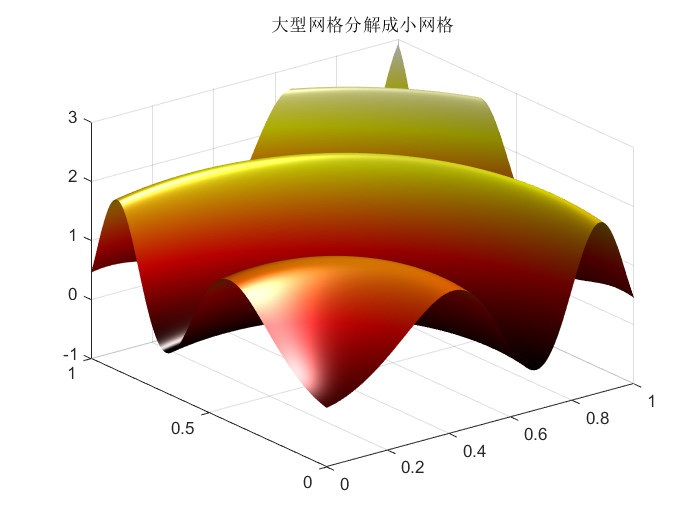

% 案例三
n = 100000;
x = rand(n, 1);
y = rand(n, 1);
z = x + y + sin((x.^2 + y.^2)*10);
xnodes = 0 : 0.00125 : 1;
ynodes = xnodes;
% 大型网格化 --> 分解成小网格
[zg, xg, yg] = gridfit(x, y, z, xnodes, ynodes, 'tilesize', 120, 'overlap', 0.25);
figure
surf(xg, yg, zg)
shading interp
colormap(hot)
camlight right
lighting phong
title('大型网格分解成小网格');